# Chapter 4: Friedkin-Johnsen model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 4.1 Firedkin-Johnsen model

This model introduced a discrete-time modification of the dynamics [M3.2](matlab:open('./ch03_taylor.mlx')). This model has been experimentally validated for small and medium-size groups.

Similar to DeGroot's dynamics [M1.1](matlab:open('./ch01_fdg.mlx')), the Friedkin-Johnsen model employs a stochastic matrix of social infleunces $W$, corresponding to the influence graph $\mathcal G[W]$. 

Beside this matrix, a diagonal matrix $\Lambda = diag(\lambda_1, \dots, \lambda_n)$ is introduced, where $\lambda_i \in [0,1]$ stands for the susceptibility of agent $i$ to the process of social influence. 

The vector of the agents' opinion evolves in accordance with 

                                                                            (M4.1)$x(k+1) = \Lambda W x(k) + (I-\Lambda)u$

Here $u$ is a constant vecotr of the agents' prejudices. 

The susceptibilities' complements $1-\lambda_i$ play the same role as the coefficients $\gamma_i$ in model [M3.2](matlab:open('./ch03_taylor.mlx')).

- $\Lambda = 0$ the model M4.1turns into the French-DeGroot model [M1.1](matlab:open('./ch01_fdg.mlx'))

- If $1-\lambda_i=0$ then agent $i$ is independent of the prejudice vector $u$ and applies the usual French-DeGroot rule

- When $\lambda_i<1$ agent i is anchored to its prejudice $u_i$ and factors its intro any opinion iteration.

- If $\lambda_i =0$ then the $i$-th agents' opinion stabilizes at the first tep $x_i(k) \equiv u_i \ \forall k \ge 1$; such an agent is stubborn $x_i(k) \equiv x_i(0)$ when $u_i \equiv x_i(0)$

In the Friedking-Johnsen theory it is supposed traditionally that $u 0 x(0)$, ie the prejudices of the agents are their initial opinions. This assumption motivates to adopt the "coupling condition" $1-\lambda_i = w_{ii}$ stating that the levels of agent's anchorage to the initial opinions are determined by their self-confidence weights. At the same time the prejudice may be independet of the initial opinion, for this reason we do not adopt these coupling conditions in this tutorial.

## 4.2 Convergence and stability conditions

We call agent $i$ **prejudiced** if $\lambda_i<1$, ie the prjudice $u_i$ influences its opinion at each step $k$

We split agents in two classes:

- Agent $i$ is said to be **P-dependent **(prejudice dependent, for simplicity **PD**) if is either prejudiced or influenced by some prejudiced agent $j$ (ie: a walk from $j$ to $i$ exists in the graph $\mathcal G [A]$).

- Agent i is said to be **P-independent **(for simplicity **PI**) otherwise.

Assume agents $1, \dots,r\ge 1$ are PD and agents $r+1,\dots,n$ are PI (possibly $r=n$). Denote the corresponding parts of the opinion vecotr by, respectively, $x_1(t)\in\mathbb R^r$ and $x_2(t)\in\mathbb R^{n-r}$. 

Since PD agents are, by definition, not prejudiced ($\lambda_i = 1$), then  M4.1 is decomposed as

                                                        (M4.1.1)$x_1(k+1) = \Lambda^{11}[W^{11}-x_1(k)+W^{12}x_2(k)]-(I-\Lambda^{11})u_1$

                                                                                (M4.1.2)$x_2(k+1) = W^{22}x_2(k)
$

The matrix $W^{22}$ is a stochastic matrix, ie the PI agents obey the French-DeGroot model.

**Theorem 4.1 **Let the community have $r\ge1$ PD agents and $n-r\ge0$ PI ones. Then the subsystem M4.1.1 is asymptotically stable, ie $\Lambda^{11}W^{11}$ is Schur stable $\rho(\Lambda^{11}W^{11})<1$. The model M4.1 is convergent $\iff$ $r=n$ or M4.1.2 is convergent, ie $W^{22}$ is regular. In this case:

                                                                            (E4.1)    $x^1(\infty) = V[u^1, x^2(\infty)]^T \\
V \triangleq (I_r -\Lambda^{11}W^{11})^{-1}[I_r-\Lambda^{11}, \ \Lambda^{11}W^{12}]$

The matrix $V$is stochastic, ie the final opinion of any agent is a convex combination of the prejudices and final opinions of PI agents.

**Corollary 4.1 **The Friedkin-Johnsen model M4.1 is asymptotically stable $\iff$ all agents are PD. Then $V = (I- \Lambda W)^{-1}(I-\Lambda)$. This holds, in particular, if $\Lambda < I_n$ or $\Lambda \neq I_n$ and $\mathcal G[W]$ is strongly connected ( $W$ is irreducibile).

**Corollary 4.2 **The model M4.1 converges $\iff$ $A = \Lambda W$ is regular, ie the limit $\lim_{k \rightarrow \infty}A^k$ exists

% esempio 3 del paper

## 4.3 Friedkin's influence centrality and PageRank

A natural question arises whether the concept of social power can be extended to model M4.1. Such extension will be based on the equality E4.1. We confine ourselves to the case of asymptotically stable model M4.1 with the prejudice vector $u = x(0)$, hence $x(\infty) = Vx(0)$ where $V = (I - \Lambda W)^{-1}(I-\Lambda)$.

French's social power assumed that the angets converge to the same consensu opinion $x_1(\infty) = \dots = x_n(\infty)$; the social power of agent $i$ is defined as the weight of its initial opinion $x_i(0)$ in this final opinion of the group.

FJ models provides a generalization of social power of agent $i$ as the mean weight of its initial opinion in determining group members' final opinions. Mathematically, these mean infleunce wieghts are elements of the non-negative vector $c \triangleq n^{-1}V^T\mathbb 1_n$, which satisfies the following equality

                                                                        (E4.2)$\bar x = \frac1n\sum^n_{i=1} x_i(\infty) = \frac1n \mathbb 1_n^TVx(0) = c^Tx(0)$

We call $c_i$ the *influence centrality *of agent $i$. Since $V$ is stochastic, $c^T \mathbb 1_n=1$. 

Similar to French's social power, the influence centrality is generated by an opinion formation mechanism. Choosing a stochastic matrix $W$, adapted to  given graph $\mathcal G$ with $n$ nodes, and some diagonal matrix $\Lambda$, Friedkin's construction gives a very insightful and broad class of centrality measures. 

For a fixed $W$, let $\Lambda = \alpha I_n$ with $\alpha \in (0,1)$ and consider the corresponding matrix $V_\alpha$ and vector $c_\alpha$. Obviously, $c_0 = n^{-1}\mathbb 1_n$, ie the social power is uniformly distributed between all the agents. As $\alpha \rightarrow 1$, the vector $c_\alpha$ converges to French's social power (when it exists).

**Lemma 4.1 **Let $W$ be a fully regular matrix and $p_\infty$ stand for the vector of French's social power, corresponding to the model  [M1.1](matlab:open('./ch01_fdg.mlx')). Then $p_\infty = \lim_{\alpha \rightarrow 1-0}c_\alpha$

Indeed $V_\alpha = (1-\alpha)(I-\alpha W)^{-1}\rightarrow W^\infty$ for $\alpha \rightarrow 1^-$, where $W^\infty = \lim_{k \rightarrow \infty}W^k = \mathbb 1_np^T$. Thus $c_\alpha = n^{-1}V_\alpha^T\mathbb 1_n \rightarrow p_\infty$ for $\alpha \rightarrow 1^-$.

The class of Friedkin's centrality measures $f_\alpha$ contains the well-known PageRank. The relation between the influence centrality and PageRank follows from the contruction of PageRank via random surfing.

Consider a segment of WWW with $n$ web pages and a stochastic $n\times n$ hyperlink matrix $W=(w_{ij})$, where $w_{ij}>0$ $\iff$ a hyperlink leads from the i-th webpage to the j-th one. Such weight represents the probability to choose hyperlink to webpage $j$ from webpage $i$

Random surfing is a Markov process; denoting the probability to open webpage $i$ on step $k$ by $p_i(k)$, the row vector $p(k)^T = (p_1(k),\dots, p_n(k))$ obeys the dual FDG (TODO: MANCA LINLK CON FDG PERCHé NON HO FATTO BENE QUELLA PARTE).

If the French social power vector $p_\infty$ is well-defined, then the probability distribution $p(k)$ converges to $p_\infty$. Since $p_\infty^T = p^TW$, the vector $p_\infty$ satisfies the natural principle of webpage ranking: a webpage referred by highly ranked webpages should also get a high rank. However, the web graphs are often disconnected, so $W$may be not fully regular, ie the French's social power may not exist. To avoid this problem, the Markov process of random surfing is modified, allowing the teleportation from each node to a randomly chosen webpage. 

With probability $m\in(0,1)$, at each step the surfer "gets tired" and opens a random webpage, sampled from the uniform distribution. The Markov Chain (QUELLA DI FDG MANCANTE) is replaced by 

                                                                        (M4.2)$p(k+1)^T = (1-m)p(k)^TW+\frac mn \mathbb 1_n^T
$

which is dual to the FJ model M4.1 with $\Lambda = (1-m)I_n$. 

It can be easily shown  that $p(k)^T \rightarrow c^T_{1-m} = \frac mn \mathbb 1_n^T(1-(1-m)W)^{-1}$, since is a special case of Friedkin's influence centrality, this limit probability is referred to as PageRank (Google algorithm used $m=0.15$).

## 4.4 Alternative interpretations and extensions

## 4.5 Examples

Three examples. The first puts the model beside French-DeGroot on a topology already used in Chapter 1; the second makes the decomposition of section 4.2 visible and shows what decides convergence; the third builds the influence centrality of section 4.3 and arrives at PageRank. Throughout the prejudices are the initial opinions, u = x(0), which is the case section 4.3 confines itself to.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];      % the initial condition used in Chapter 1
K  = 60;

fprintf('N = %d agents,  u = x(0)\n', N);

N = 6 agents,  u = x(0)


## 4.5.1 What susceptibility changes

The directed cycle is the topology on which the French-DeGroot model never settles: it is strongly connected but has period 6, so all six eigenvalues of W sit on the unit circle and the opinions rotate forever. Corollary 4.1 says that with Lambda different from I and W strongly connected the Friedkin-Johnsen model is asymptotically stable, so the same topology should now converge.

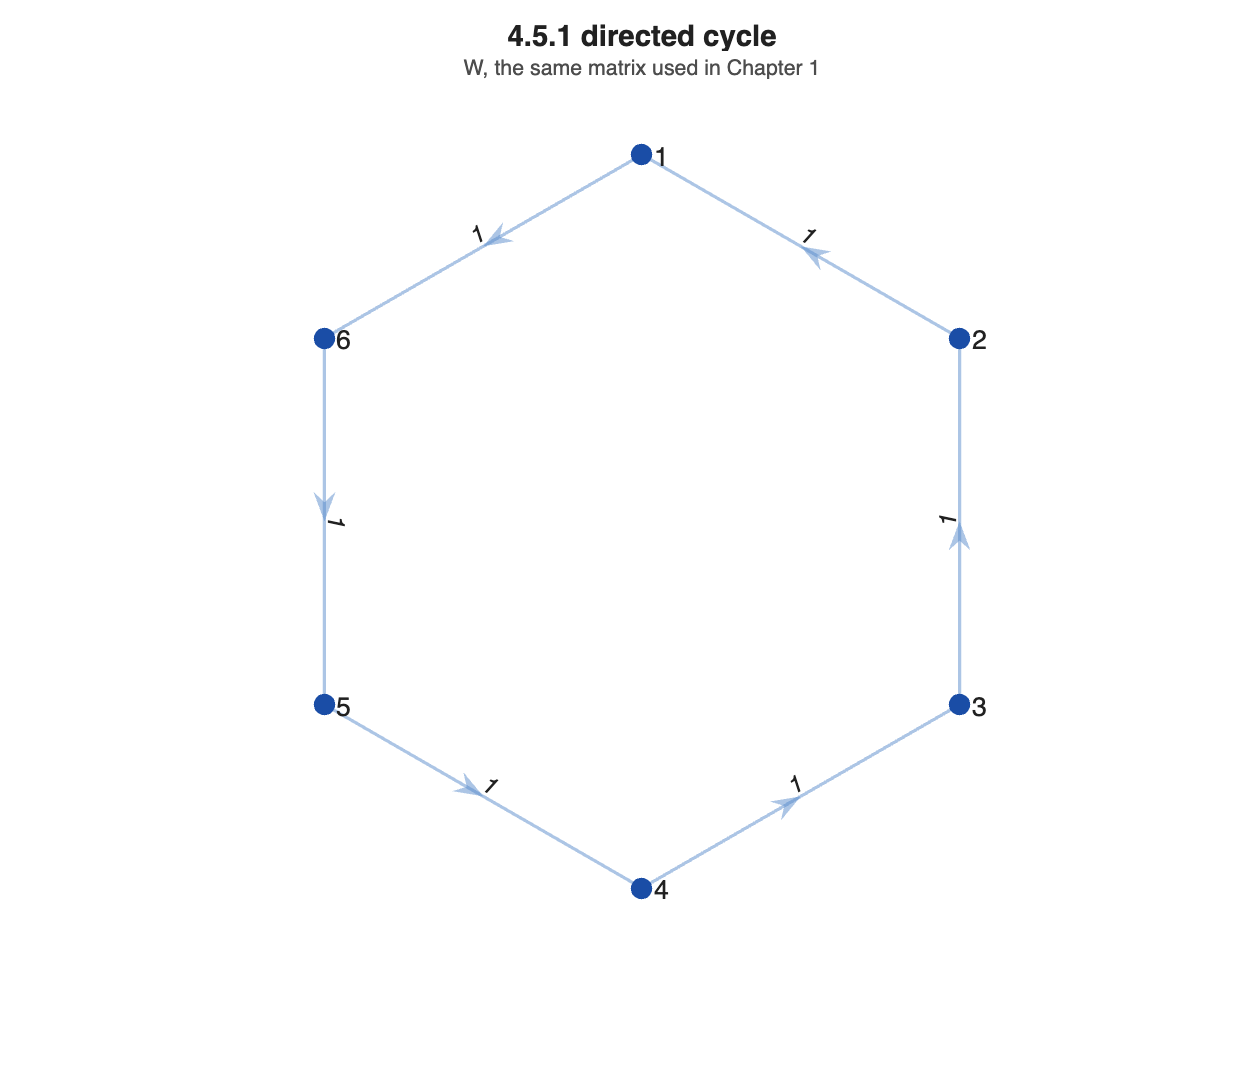

W = row_stochastic(ring_graph(N));
u = x0;

figure('Position',[0 0 620 540]);
plot_graph(W, [], 'Title','4.5.1 directed cycle', 'Subtitle','W, the same matrix used in Chapter 1')


fprintf('rho(Lambda W)   lambda = 1.0 : %.4f   (French-DeGroot)\n', max(abs(eig(W))));

rho(Lambda W)   lambda = 1.0 : 1.0000   (French-DeGroot)


for lam = [0.9 0.7]
    fprintf('                lambda = %.1f : %.4f\n', lam, max(abs(eig(lam*W))));
end

                lambda = 0.9 : 0.9000
                lambda = 0.7 : 0.7000


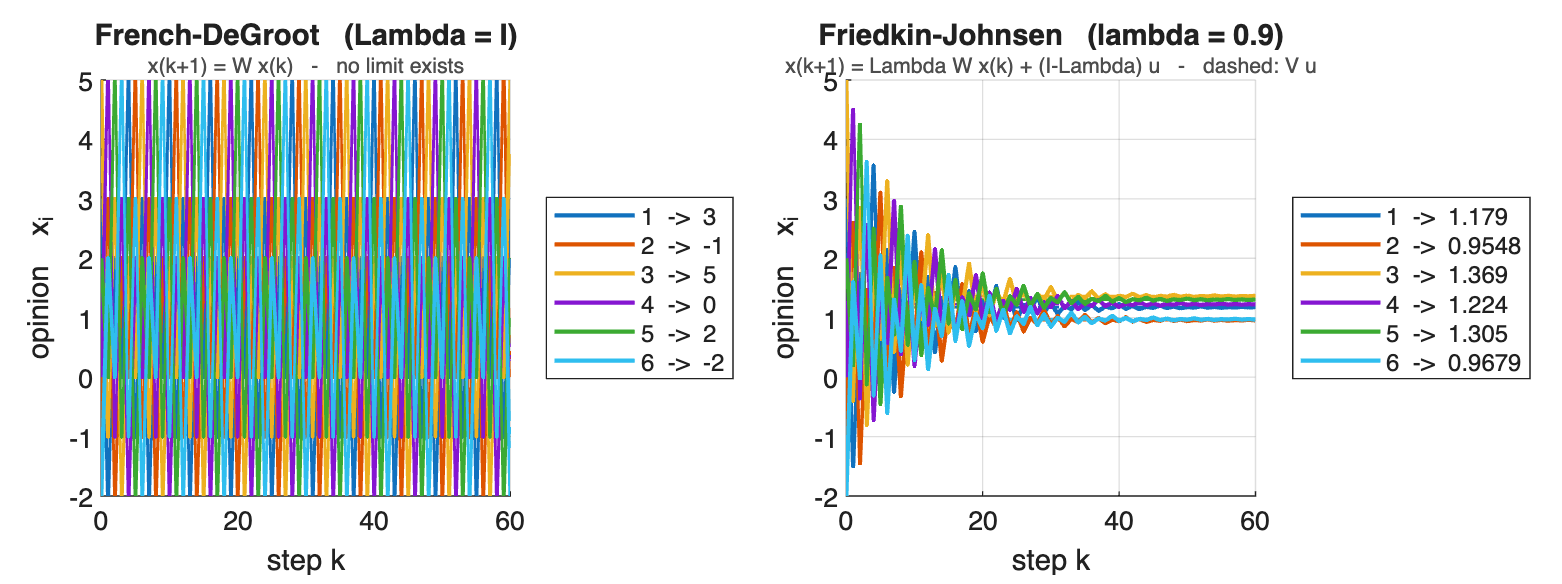

lam = 0.9;
Xfdg = sim_degroot(W, x0, K);                              % Lambda = I
Xfj  = sim_friedkin_johnsen(W, lam*ones(N,1), u, x0, K);   % Lambda = 0.9 I
V    = total_influence(W, lam*ones(N,1));

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xfdg, [], 'Title','French-DeGroot   (Lambda = I)', ...
    'Subtitle','x(k+1) = W x(k)   -   no limit exists');
nexttile;
plot_opinions(Xfj, [], 'Limit', V*u, 'Title','Friedkin-Johnsen   (lambda = 0.9)', ...
    'Subtitle','x(k+1) = Lambda W x(k) + (I-Lambda) u   -   dashed: V u');

The spectrum says why. With Lambda = lambda I the matrix Lambda W is lambda W, so the six eigenvalues keep their arrangement and are scaled towards the origin by exactly lambda: the unit circle stops being reachable as soon as lambda < 1.

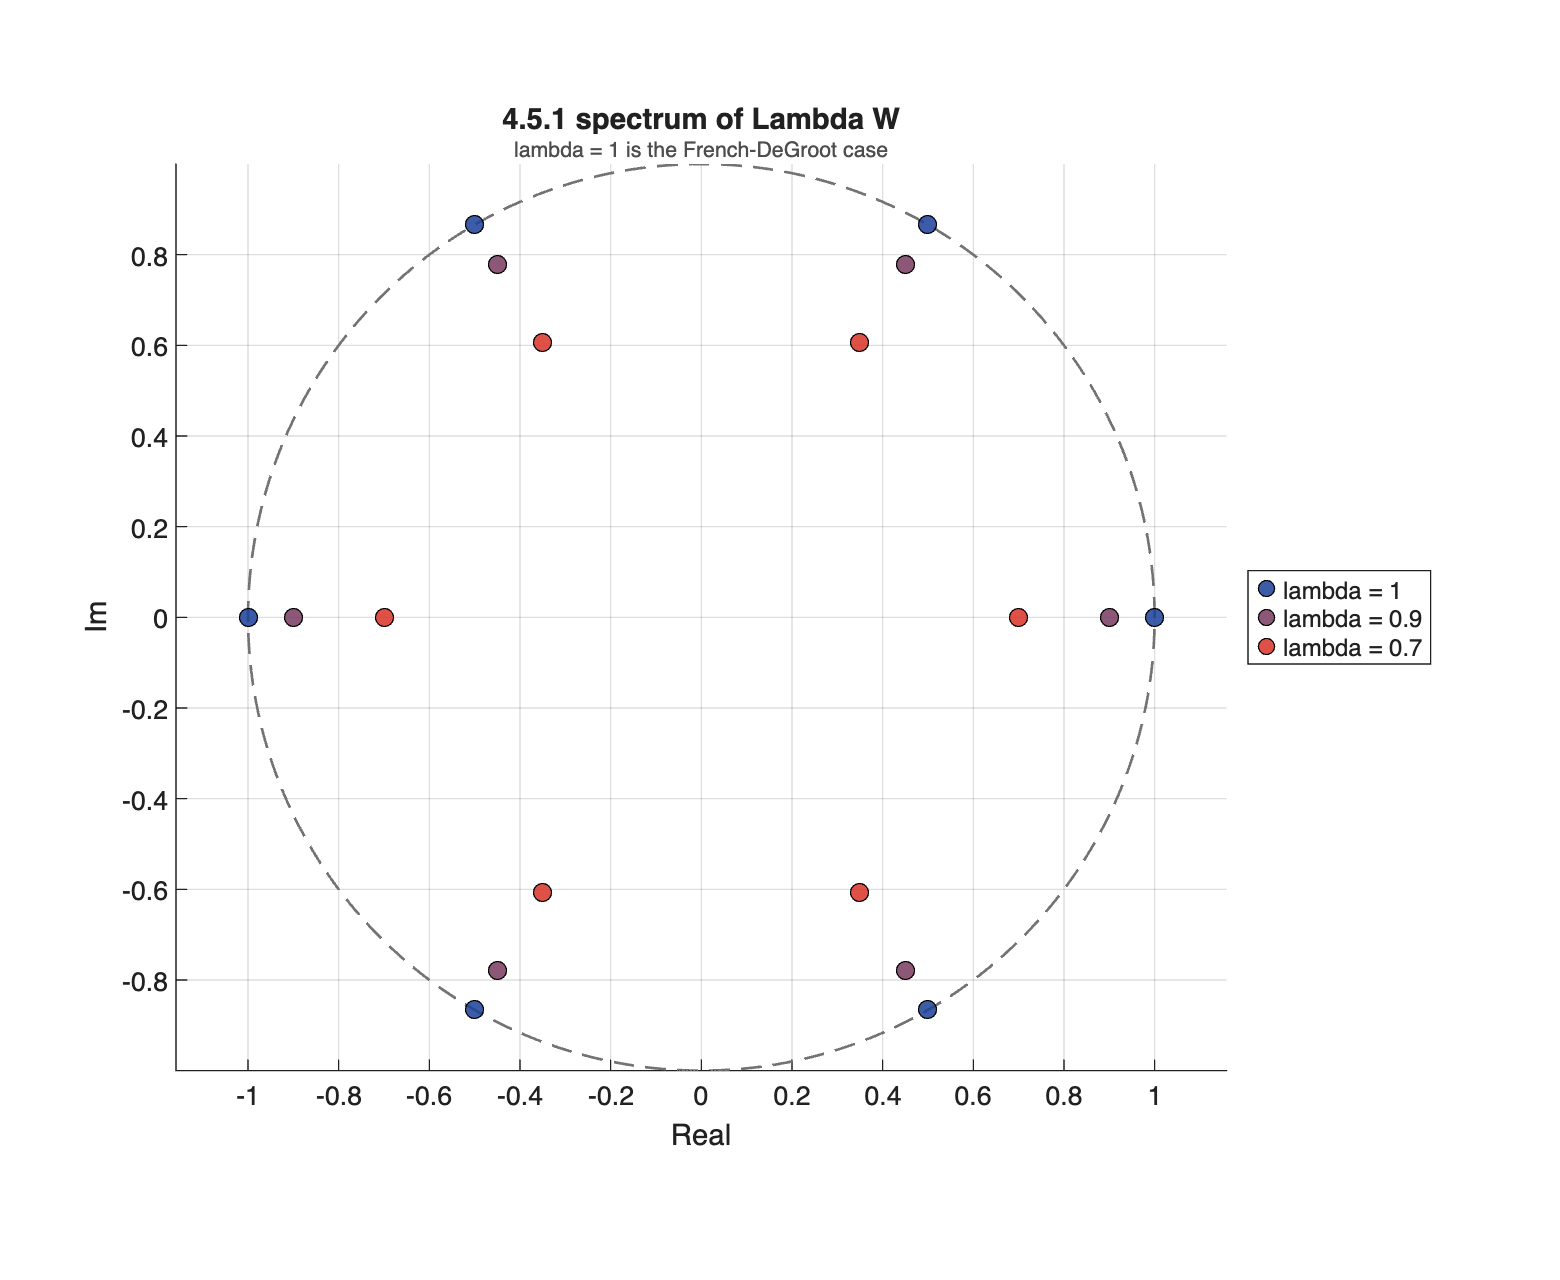

figure('Position',[0 0 780 640]);
plot_spectrum_family({W, 0.9*W, 0.7*W}, [1 0.9 0.7], 'discrete', 'View','complex', ...
    'Label','lambda', 'Title','4.5.1 spectrum of Lambda W', ...
    'Subtitle','lambda = 1 is the French-DeGroot case');


fprintf('rank of the French-DeGroot limit operator : %s\n', 'not defined, W is periodic');

rank of the French-DeGroot limit operator : not defined, W is periodic


fprintf('rank(V) for lambda = %.1f                  : %d of %d\n', lam, rank(V), N);

rank(V) for lambda = 0.9                  : 6 of 6


fprintf('spread of V*u                             : %.4f\n', max(V*u) - min(V*u));

spread of V*u                             : 0.4042


Two things changed at once. The model now converges, and it converges to disagreement: V has full rank, so each agent keeps a trace of its own prejudice instead of the group collapsing onto a single value. In Chapter 1 a rank-one limit operator was the signature of consensus; here the rank is the signature of persistent, bounded cleavage.

## 4.5.2 The decomposition, and what decides convergence

Section 4.2 splits the agents into P-dependent ones, which some prejudice reaches, and P-independent ones, which none does, and writes the model as (M4.1.1) and (M4.1.2). The second block is driven by W22 alone and is therefore an ordinary French-DeGroot model. In the network below only agent 1 is prejudiced, and agents 4, 5, 6 form a group that listens only to itself.

Wb = zeros(N);
Wb(1,2) = 1;                        % 1 is prejudiced and listens to 2
Wb(2,1) = 0.5;  Wb(2,4) = 0.5;      % 2 listens to 1 and to the other group
Wb(3,2) = 1;                        % 3 listens to 2
Wb(4,6) = 1;  Wb(5,4) = 1;  Wb(6,5) = 1;     % a directed 3-cycle, closed on itself

lambda = [0.5; 1; 1; 1; 1; 1];      % only agent 1 is prejudiced
u      = x0;

pd = prejudice_reach(Wb, lambda < 1);
p1 = find(pd).';   p2 = find(~pd).';
fprintf('prejudiced (lambda < 1) : %s\n', mat2str(find(lambda < 1).'));

prejudiced (lambda < 1) : 1


fprintf('P-dependent   (PD)      : %s\n', mat2str(p1));

P-dependent   (PD)      : [1 2 3]


fprintf('P-independent (PI)      : %s\n', mat2str(p2));

P-independent (PI)      : [4 5 6]


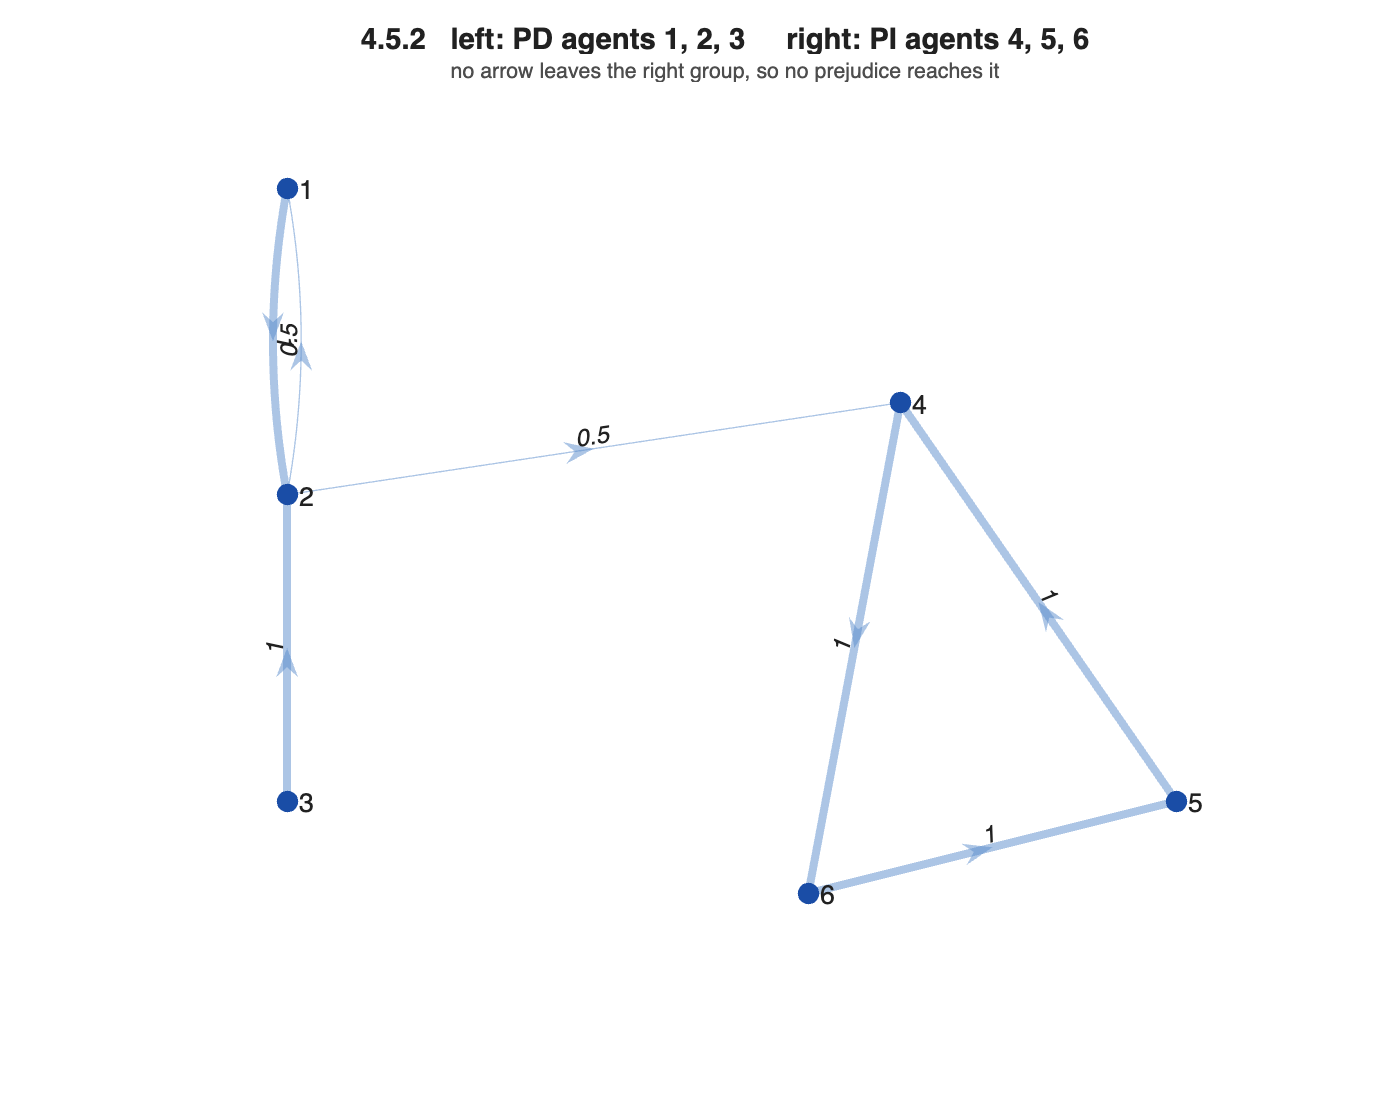


pos = zeros(N,2);
pos(p1,:) = [zeros(3,1), (3:-1:1).'];
pos(p2,:) = [2.0 2.3; 2.9 1.0; 1.7 0.7];

figure('Position',[0 0 700 560]);
plot_graph(Wb, [], 'Layout', pos, ...
    'Title','4.5.2   left: PD agents 1, 2, 3     right: PI agents 4, 5, 6', ...
    'Subtitle','no arrow leaves the right group, so no prejudice reaches it')

L11 = diag(lambda(p1));
W11 = Wb(p1,p1);
W22 = Wb(p2,p2)

W22 =      0     0     1
     1     0     0
     0     1     0



fprintf('rho(Lambda11 W11) = %.4f   -> Schur stable = %d   (Theorem 4.1)\n', ...
    max(abs(eig(L11*W11))), max(abs(eig(L11*W11))) < 1);

rho(Lambda11 W11) = 0.5000   -> Schur stable = 1   (Theorem 4.1)


fprintf('W22 is stochastic : %d   period %d   regular = %d\n', ...
    is_row_stochastic(W22), graph_period(W22), graph_summary(W22).convergent);

W22 is stochastic : 1   period 3   regular = 0


Theorem 4.1 guarantees the first block whatever the rest of the network does: Lambda11 W11 is Schur stable. It does not guarantee the second, and here W22 is a directed 3-cycle, so it is periodic and not regular. The two spectra show the difference directly.

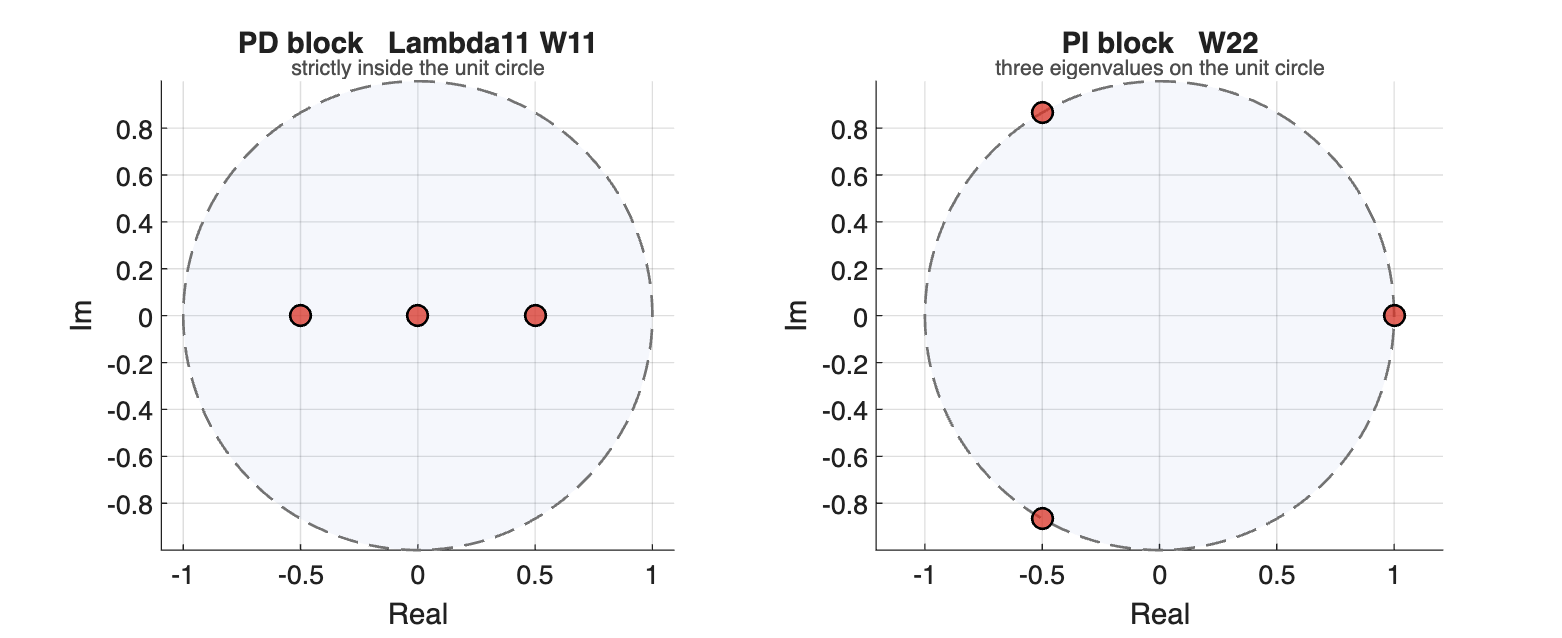

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_eigenvalues(L11*W11, 'discrete', 'Title','PD block   Lambda11 W11', ...
    'Subtitle','strictly inside the unit circle');
nexttile;
plot_eigenvalues(W22, 'discrete', 'Title','PI block   W22', ...
    'Subtitle','three eigenvalues on the unit circle');

Plotting the two state components separately shows the consequence. The P-dependent agents settle; the P-independent ones cycle forever, and because the first block is driven by the second, nothing settles.

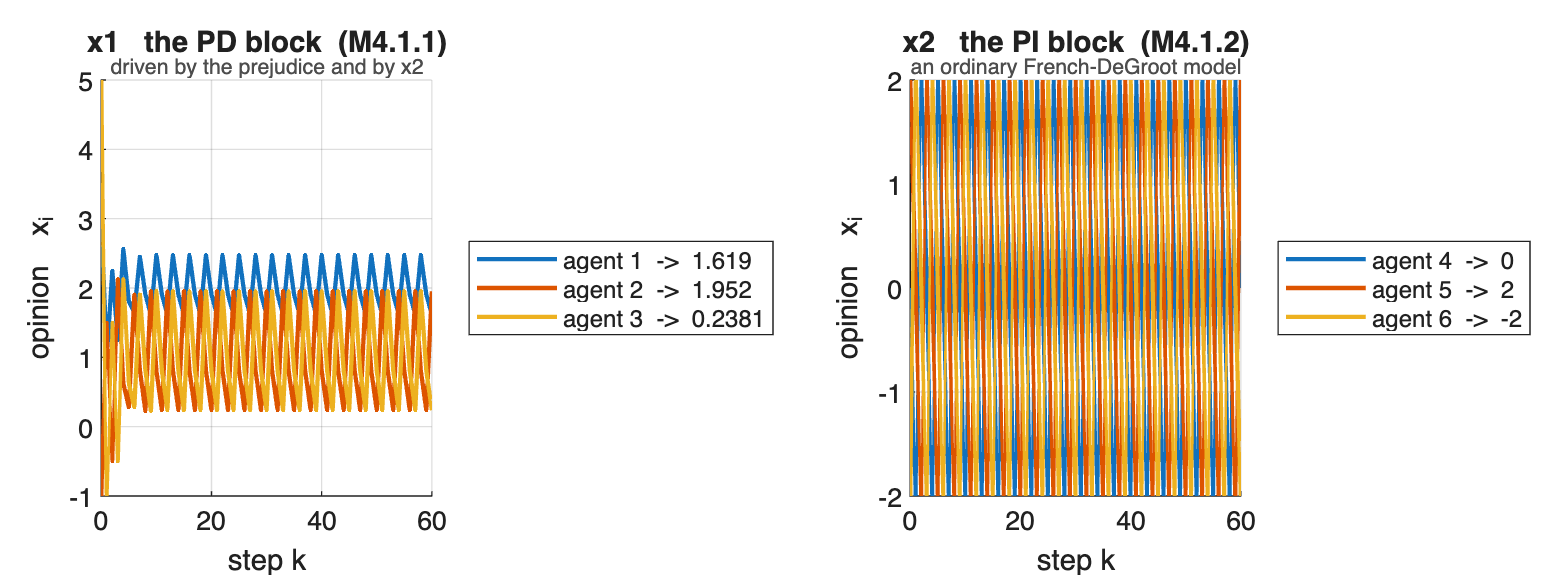

X = sim_friedkin_johnsen(Wb, lambda, u, x0, K);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(X(p1,:), [], 'Labels', compose('agent %d', p1), ...
    'Title','x1   the PD block  (M4.1.1)', 'Subtitle','driven by the prejudice and by x2');
nexttile;
plot_opinions(X(p2,:), [], 'Labels', compose('agent %d', p2), ...
    'Title','x2   the PI block  (M4.1.2)', 'Subtitle','an ordinary French-DeGroot model');


fprintf('settled by step %d ?  %d\n', K, max(abs(X(:,end) - X(:,end-1))) < 1e-8);

settled by step 60 ?  0


Corollary 4.2 says the model converges exactly when W22 is regular, so one self-loop inside the closed group is enough to repair it. Nothing about the P-dependent block changes.

Wc = Wb;  Wc(4,4) = 0.5;  Wc(4,6) = 0.5;      % break the period of the closed group

fprintf('W22 period %d -> %d,   regular = %d\n', graph_period(Wb(p2,p2)), ...
    graph_period(Wc(p2,p2)), graph_summary(Wc(p2,p2)).convergent);

W22 period 3 -> 1,   regular = 1


fprintf('rho(Lambda11 W11) unchanged : %.4f\n', max(abs(eig(diag(lambda(p1))*Wc(p1,p1)))));

rho(Lambda11 W11) unchanged : 0.5000


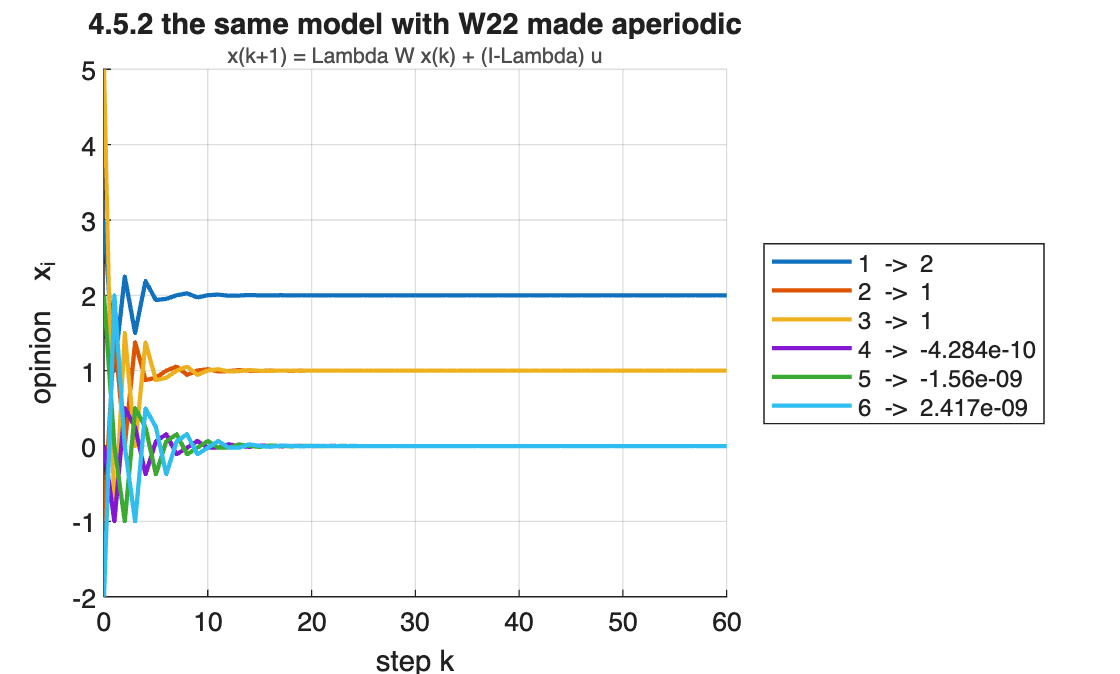


Xc = sim_friedkin_johnsen(Wc, lambda, u, x0, K);

figure;
plot_opinions(Xc, [], 'Title','4.5.2 the same model with W22 made aperiodic', ...
    'Subtitle','x(k+1) = Lambda W x(k) + (I-Lambda) u')


fprintf('settled by step %d ?  %d\n', K, max(abs(Xc(:,end) - Xc(:,end-1))) < 1e-8);

settled by step 60 ?  1


This is where the discrete-time model departs from its continuous-time counterpart. There the P-independent block was an Abelson model, which converges for any weights, so the whole system always converged. Here the P-independent block is a French-DeGroot model, which can be periodic, so asymptotic stability of the P-dependent block is not enough and Corollary 4.2 has real content.

## 4.5.3 Influence centrality and PageRank

Section 4.3 asks how social power extends to this model. With u = x(0) the limit is x(inf) = V x(0), and since the agents do not agree there is no single final opinion to weigh against; (E4.2) averages agent is weight across all the final opinions instead. The network below is the small asymmetric one from Chapter 1, whose French social power is already known.

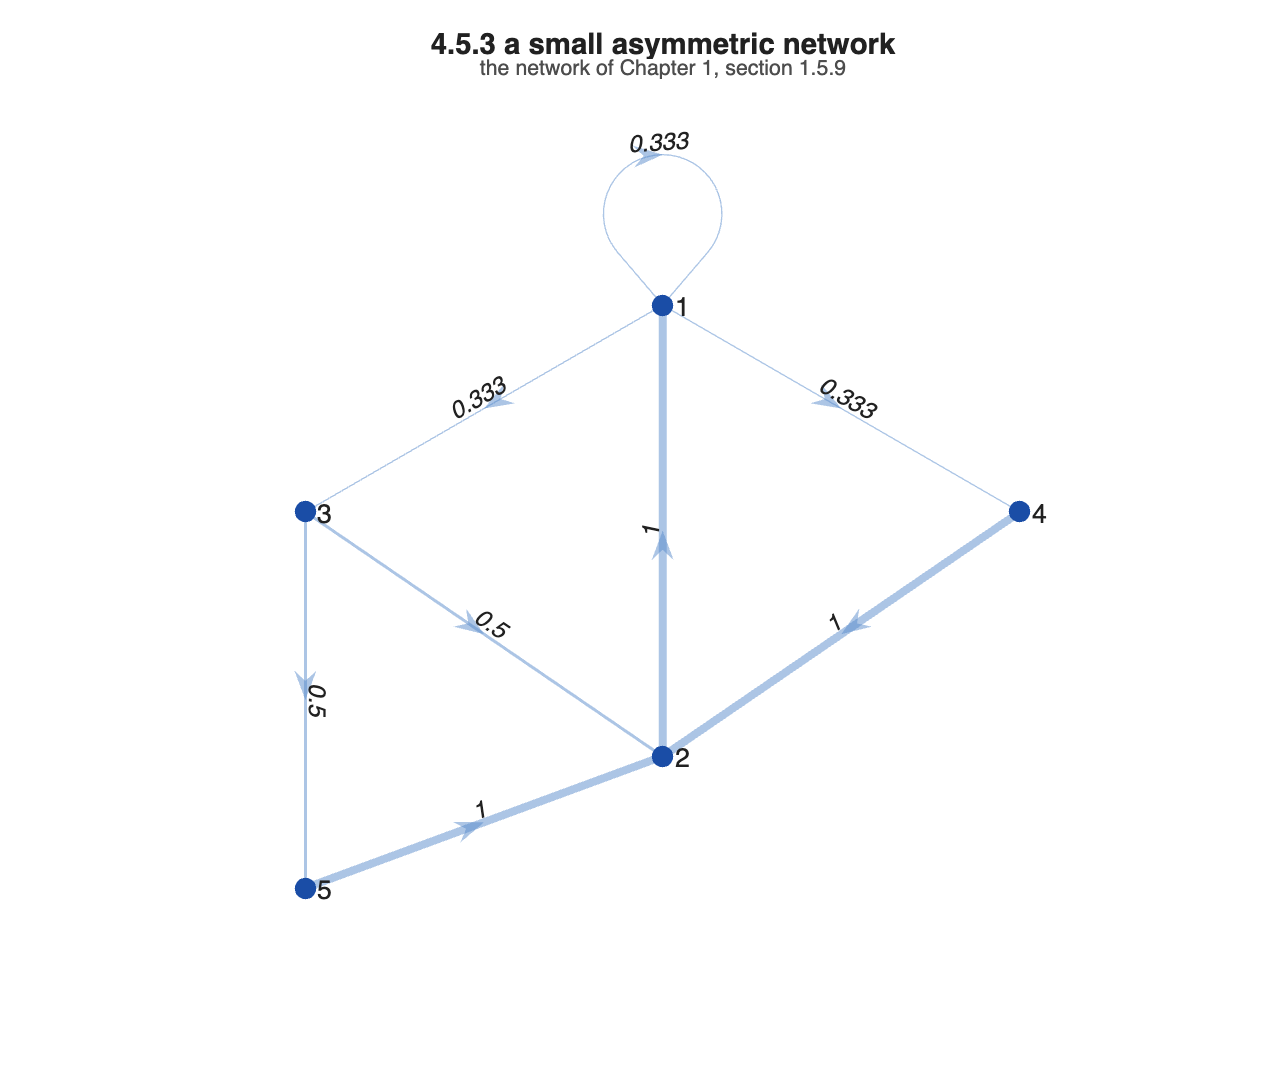

A = [1 0 1 1 0        % 1 listens to itself, to 3 and to 4
     1 0 0 0 0        % 2 listens only to 1
     0 1 0 0 1        % 3 listens to 2 and to 5
     0 1 0 0 0        % 4 listens only to 2
     0 1 0 0 0];      % 5 listens only to 2
Wc5 = row_stochastic(A);
n   = 5;

posc = [0 1.2; 0 -1.2; -1.9 0.1; 1.9 0.1; -1.9 -1.9];
figure('Position',[0 0 640 540]);
plot_graph(Wc5, [], 'Layout', posc, 'Title','4.5.3 a small asymmetric network', ...
    'Subtitle','the network of Chapter 1, section 1.5.9')


p = social_power(Wc5);
fprintf('French social power p = %s\n', mat2str(round(p.',4)));

French social power p = [0.4 0.2667 0.1333 0.1333 0.0667]


lam = 0.85;
V   = total_influence(Wc5, lam*ones(n,1));
c   = influence_centrality(Wc5, lam)

c =     0.3686
    0.2755
    0.1344
    0.1344
    0.0871


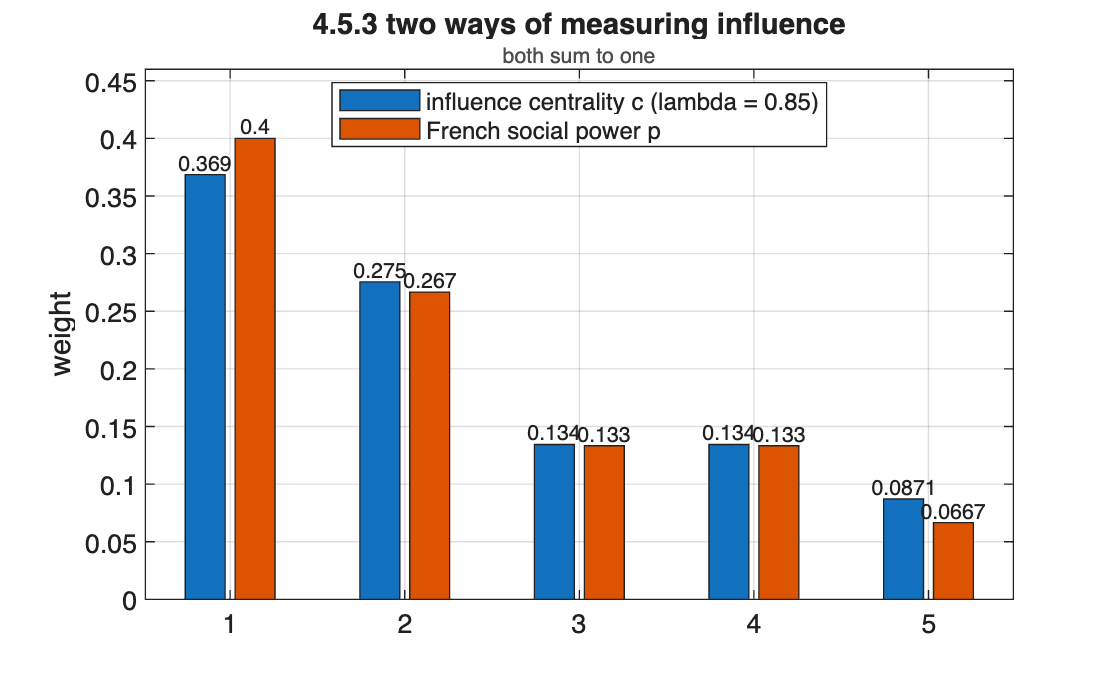


figure;
plot_bars([c, p], [], 'Series', {'influence centrality c (lambda = 0.85)', ...
    'French social power p'}, 'YLabel','weight', ...
    'Title','4.5.3 two ways of measuring influence', 'Subtitle','both sum to one')

They rank the agents almost the same way here but they are not the same quantity. Lemma 4.1 says the second is the limit of the first: as lambda goes to one, c(lambda) tends to p. At the other end lambda = 0 gives V = I and influence spread equally.

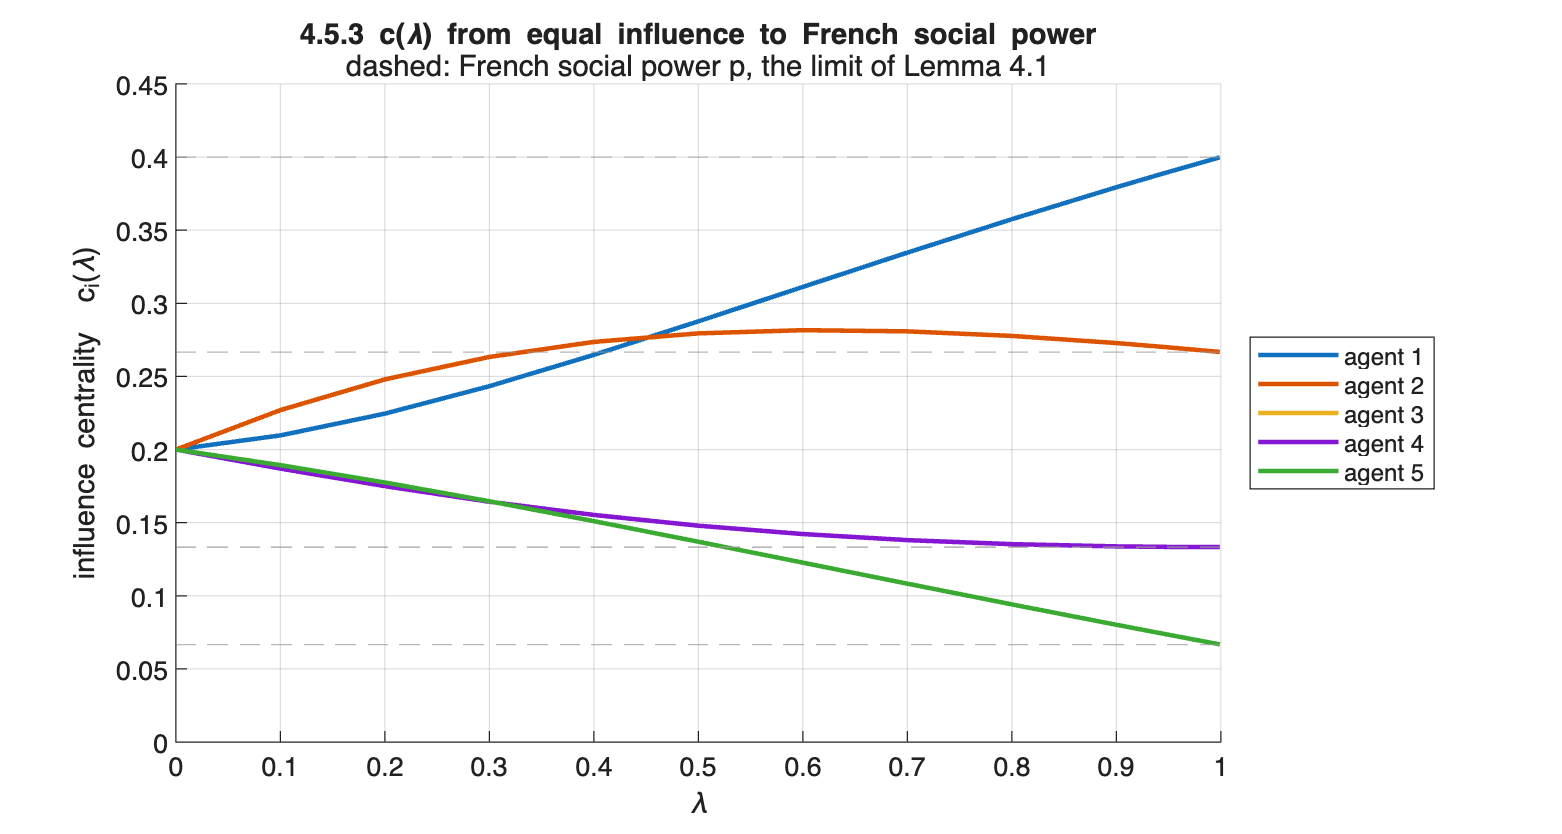

lams = [0 0.1:0.1:0.9 0.95 0.99 0.999];
Cs   = zeros(n, numel(lams));
for j = 1:numel(lams), Cs(:,j) = influence_centrality(Wc5, lams(j)); end

figure('Position',[0 0 880 470]); hold on
h = plot(lams, Cs.', 'LineWidth', 1.7);
for i = 1:n, yline(p(i), '--', 'Color', [.6 .6 .6]); end
legend(h, compose('agent %d', 1:n), 'Location','eastoutside');
grid on; xlabel('\lambda'); ylabel('influence centrality  c_i(\lambda)');
xlim([0 1]); ylim([0 0.45]);
title('4.5.3 c(\lambda) from equal influence to French social power', 'FontWeight','bold');
subtitle('dashed: French social power p, the limit of Lemma 4.1');


fprintf('c(0) is exactly uniform: max|c(0) - 1/n| = %.2e\n\n', ...
    max(abs(Cs(:,1) - 1/n)));

c(0) is exactly uniform: max|c(0) - 1/n| = 0.00e+00



fprintf('  lambda    spread of c    ||c - p||    ranking\n');

  lambda    spread of c    ||c - p||    ranking


for j = [2 3 4 7 10 12 13]
    [~, ord] = sort(Cs(:,j), 'descend');
    fprintf('  %-8g  %.4f         %.4f       %s\n', lams(j), ...
        max(Cs(:,j)) - min(Cs(:,j)), max(abs(Cs(:,j)-p)), mat2str(ord.'));
end

  0.1       0.0400         0.1903       [2 1 5 3 4]
  0.2       0.0730         0.1754       [2 1 5 3 4]
  0.3       0.0990         0.1567       [2 1 5 3 4]
  0.6       0.1885         0.0888       [1 2 3 4 5]
  0.9       0.2991         0.0207       [1 2 4 3 5]
  0.99      0.3300         0.0020       [1 2 3 4 5]
  0.999     0.3330         0.0002       [1 2 3 4 5]


The ranking itself depends on lambda. At low susceptibility the agents barely pass opinions on, so influence is close to being counted by direct listeners and agent 2, listened to by three agents, leads. As lambda grows, influence travels along chains and agent 1 takes over, because it is listened to by agent 2. Susceptibility controls how far influence is allowed to propagate before it is discounted.

That is exactly the role of the damping factor in PageRank. The damped random surfer of (M4.2) is the dual chain of this model with Lambda = (1-m) I, so its limiting distribution is an influence centrality and nothing else has to be computed.

m   = 0.15;                                  % the value used by Google
cpr = influence_centrality(Wc5, 1-m);

q = [0 0 0 0 1];                             % start the surfer anywhere
for k = 1:400
    q = (1-m) * q * Wc5 + (m/n) * ones(1,n); % (M4.2)
end

fprintf('influence centrality, lambda = 1 - m : %s\n', mat2str(round(cpr.',6)));

influence centrality, lambda = 1 - m : [0.368562 0.275455 0.134426 0.134426 0.087131]


fprintf('limit of the damped random surfer    : %s\n', mat2str(round(q,6)));

limit of the damped random surfer    : [0.368562 0.275455 0.134426 0.134426 0.087131]


fprintf('max difference                       : %.2e\n', max(abs(cpr.' - q)));

max difference                       : 2.78e-17


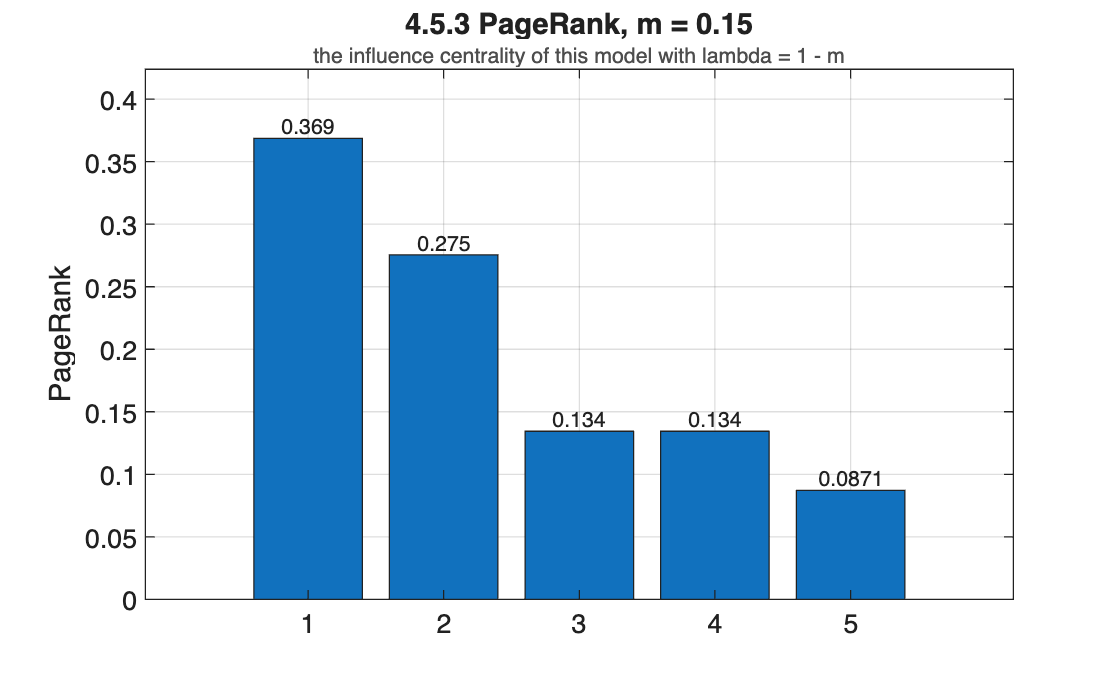


figure;
plot_bars(cpr, [], 'YLabel','PageRank', ...
    'Title','4.5.3 PageRank, m = 0.15', ...
    'Subtitle','the influence centrality of this model with lambda = 1 - m')

So the chain of the whole project closes here. Network structure fixes W; W and Lambda fix the dynamics; the dynamics fix V and with it the asymptotic influence of each agent; averaging that influence gives a centrality measure; and one member of that family, the one with lambda = 1 - m, is PageRank.